# Example: Reading and logging sensor data

In this example the data from the various sensors on the AR Drone 2.0 will be read into a program created from a Simulink model, allowing visualisation in real time and logging to the Simulink PC.

## AR Drone sensor drivers in Simulink

In order to retrieve the sensor data from the AR Drone 2.0 a driver interface is needed which can read the IMU data as it is published inside the drone filesystem at /dev/tty01. The Paparazzi open source community created a c code implementation which is able to read the data and write it into a navdata structure. A simple wrapper of the initialization, update and termination functions is therefor all that was required to be able to read the IMU data. Similairly the Paparazzi community created a c code implementation for the battery measurement which reads /dev/ic2-1, and is also wrapped to provide a Simulink block. If you wish to see how easy it is to wrap legacy c code for use in Simulink function blocks you can view the original Paparrazi and wrapper file via:

edit('BatteryMeasure.c');
edit('BatteryMeasure_Wrapper.c');

## Using the driver blocks

Both these blocks are available in the AR Drone 2 Library under the "Sensors" sub library. These library blocks are then used for the model which can visualise and save the data. To open this model evaluate the following MATLAB command:

open('Example_Reading_And_Logging_Sensor_Data.slx');

This will open the following model:

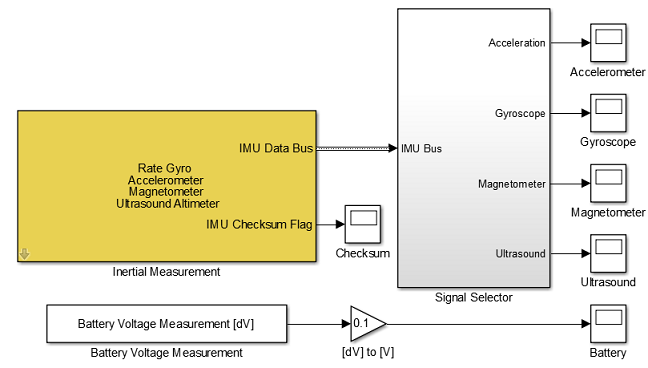

The 'IMU Data Bus' coming out of the 'Intertial Measurement' block contains the majority of the sensor information. As not all signals inside the bus are used in the Paparazii implementation nor interesting to look at it is connected to the 'Signal Selector' subsystem where a 'Bus Selector' is used to get the desired signals from the 'IMU Bus', and muxes are then used to combine the x,y and z components of the accelerometer, gyroscope and magnetometer into a single signal per sensor. The ultrasound signal and 'Battery Voltage Measurement' are single dimension signals by definition. 

In order to see the signals while the model runs on the AR Drone 2.0 the model is run in external mode. This means that signals which are connected to a scope will be send to the Simulink PC and displayed. Logging the data is done by setting each scopes 'Configuration Properties >> Logging' menu such that 'Log data to workspace' is selected. The 'Limit data points to last' index is what determines how many data points are down inside the scope before clearing the scope. For example with a setting of 20000 and the 'Interial Measurement' block set to sample at 200Hz (which is the rate at which is publishes) the scope is reset every 10 seconds. When you run the model on the drone (via the same route as the previous examples in External mode) you can click on the scopes to open them and see the data as measured on the drone.

After the program is terminated the .mat files containing the sensor data will appear in the MATLAB workspace. The amount of data saved to a mat file by the scope when using External mode is goverend by a different parameter. To set this parameter open the 'External Mode Control Panel' found under the 'Code' menu entry in the Simulink Toolbar. Under 'Configuration >> Signal & Triggering ...' you can set the 'Trigger options >> duration' amount desired. As the scopes are set to save every signal as a structure with time, twice the duration should be set as twice the data is used. The image below shows this menu with the 'Duration' setting set to 40000 for all signals, meaning 100 seconds of data will be saved when sampling the IMU block at 200Hz.

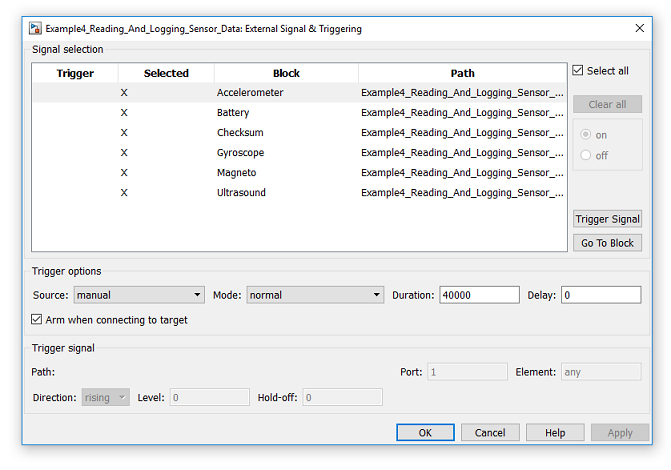

Note that the way data is stored is in intervals of the set duration, meaning that if a measurement interval has been completed all previous data will be discarded (for example using the above setting, if the model execution is stopped at 103 seconds only data from 100 till 103 seconds will be saved, with the data of the first interval from 0 to 100 seconds discarded).

## Validating IMU data integrity

Looking at the 'Inertial Measurement' Simulink block a second output is visible, the 'IMU Checksum Flag'. This output is '1' when the IMU data has passed a data integrity check, and set to '0' when the check fails. Knowing when the IMU data is valid is important for processing the data as large errors are introduced into the measurement when the 'IMU Checksum Flag' is '0'. This is illustrated in the figures below. 

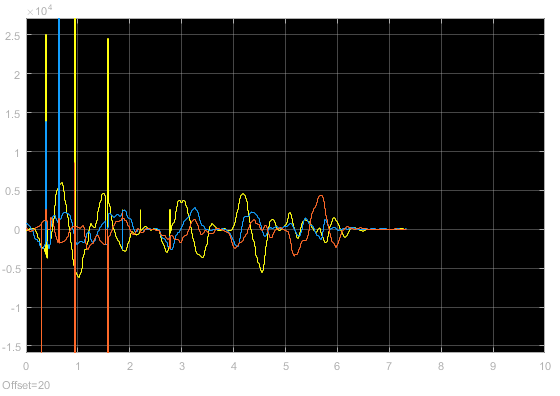

The signals in the above figure are the outputs from the three gyroscopes inside the AR Drone 2.0 IMU. The drone is moved around continuously to get significant data from the gyroscopes. A number of discontinuous peaks are visible in the data between 0 and 3 seconds, a number of which are significantly bigger than any actual data. By comparing the timestamp of these spikes to the timestamps of the 'IMU Checksum Flag' failures as seen in the figure below, the peaks are seen to be the result of corrupted navdata packages.

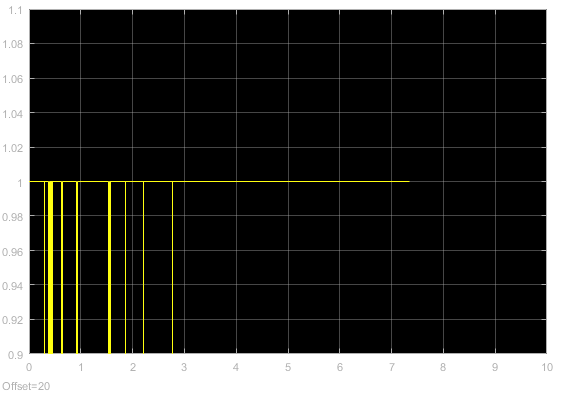

To this end any implementation reliant on the IMU data should be able to deal with these corrupted packages. The easiest recommended method is to hold the values of the last known good 'IMU Data Bus' sample if the current 'IMU Checksum Flag' is '0'.

## Understanding the ultrasound data

The ultrasound sensor positioned on the bottom of the AR Drone 2.0 faces downwards and can be used to measure the distance between the drone and a surface below it. For the best measurements the surface below the drone must be a flat horizontal surface to not scatter or misdirect the ultrasonic waves. The ultrasonic sensor polls at 25Hz and seperates the data by adding a constant value to a new measurement for the first 0.05 seconds of the sample. The figure below shows how the ultrasound measurement changes when the drone is moved such that it is positioned above a higher surface (meaning the distance from the drone to the first surface below it drops). 

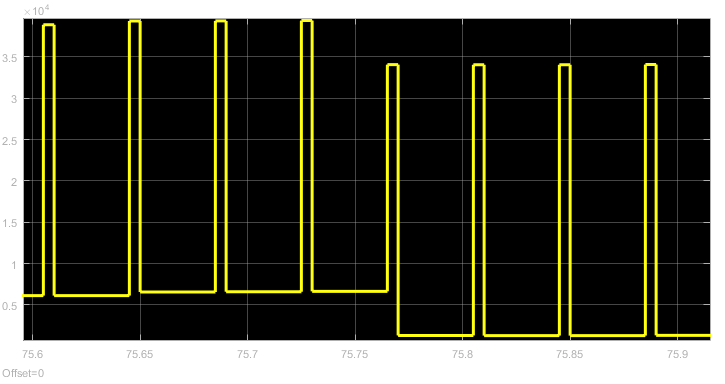

The value added as a measurement seperator is $2^{15}$ (or 32768). Dealing with these peaks requires detection of them (for example call anything larger than 30000 a peak) and then either holding the previous measurement, introducing a slight delay, or substracting $2^{15}$ from that peak to reconstruct the actual data.